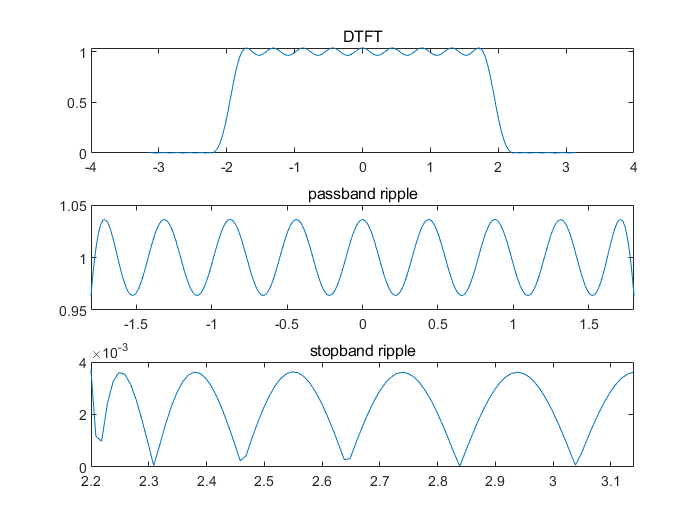

clear;close all;clc;
load nspeech2.mat;

f=[1.8,2.2];
m=[1,0];
ripple=[0.05,0.005];

[n,fo,mo,w]=firpmord(f,m,ripple,2*pi);
b=firpm(n+5,fo,mo,w);

omega_w=-pi:0.01:pi;
j=sqrt(-1);
z=exp(j*omega_w);

h_total=b(1);
for i =2:length(b)
    h_total=h_total+b(i).*z.^(-(i-1));
end

figure(1);
subplot(311);plot(omega_w,abs(h_total));title('DTFT');
subplot(312);plot(omega_w,abs(h_total));xlim([-1.8,1.8]);title('passband ripple');
subplot(313);plot(omega_w,abs(h_total));xlim([2.2,3.14]);title('stopband ripple');

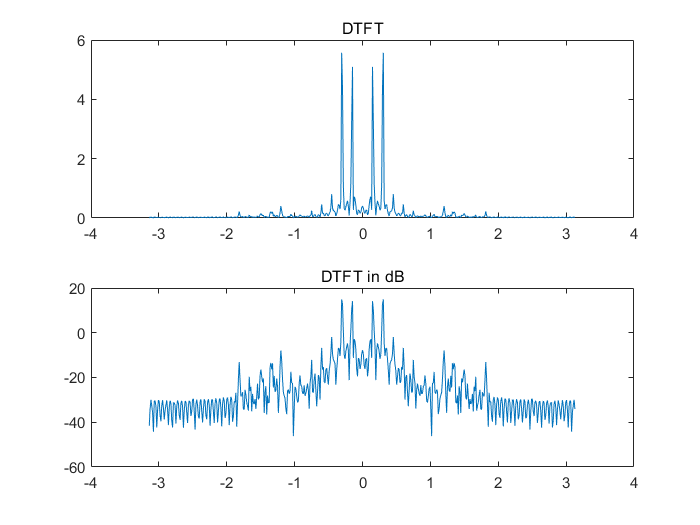

figure(2);
res=conv(b,nspeech2);
% sound(res);
[X,w]=DTFT(res(20001:20400),512);
subplot(211);plot(w,abs(X));title('DTFT');
subplot(212);plot(w,20*log10(abs(X)));title('DTFT in dB');